clear
clc
many=input('How many times do you wish to execute the program?\n');
clc
%Final answers would be stored in p (pressure distribuition)  d (delta t)
p{many}=[];
d{many}=[];
dims = [1 45];
opts.Interpreter = 'tex';
opts.Default='No';
%Initial assumption of question "change" for first run
answer='Yes';
for m=1:many
    if answer=='Yes'
        info=Input;
        %Well information
        q=wellinfo(info);
        %Boundary information
        [BC,info.Choice]=Choose;
    else
        dlgtitle2='Input Time step data...';
        prompt2='\fontsize{10}\bf\Deltat:';
        definput2 = {char(string(info.Dt))};
        data2 = inputdlg(prompt2,dlgtitle2,dims,definput2,opts);info.Dt=double(string(data2{1}));
        info.st=round(info.Time/info.Dt);
        info.Etha=(5.615*info.Bo*info.Dt)/(info.Vb*info.Phi*info.c);
    end
    % Variable (    Y-index,        X-index,       Z-index,        T-index    )
    u=zeros    (  info.s(2)+2,    info.s(1)+2,   info.s(3)+2,      info.st    );
    T.x=zeros  (  info.s(2),      info.s(1)+1,   info.s(3),        info.st    );
    T.y=zeros  (  info.s(2)+1,    info.s(1),     info.s(3),        info.st    );
    T.z=zeros  (  info.s(2),      info.s(1),     info.s(3)+1,      info.st    );
    n=0;
    [T,u]=Boundary(info,T,BC,u,n);
    M=zeros(info.s(1)*info.s(2)*info.s(3)); % Matrix of coefficients
    D=zeros(info.s(1)*info.s(2)*info.s(3),1); % Matrix of known values
    temp=zeros(info.s(1)*info.s(2)*info.s(3),1);
    tstart(m)=tic;
    dot='....';
    for n=1:info.st % Time steps
        fprintf(['Doing Calculation',dot(1:mod(n,4)+1)])
        if info.st<200
            pause(0.05)
        end
        clc
        for o=1:info.s(1)*info.s(2)*info.s(3) % o= block number
            %Cordinates of a block number: i,j,k
            i = mod(o,info.s(1));i(i==0)=info.s(1);
            j = mod(ceil(o/info.s(1)),info.s(2));j(j==0)=info.s(2);
            k = ceil(o/(info.s(1)*info.s(2)));
            %Forming a matrix of coefficients (M)
            
            % Centeral Diameter
            
            M(o,o)=   -T.y(j,i,k,n)     -T.x(j,i,k,n)       -T.z(j,i,k,n)...
                -T.x(j,i+1,k,n)   -T.y(j+1,i,k,n)     -T.z(j,i,k+1,n)...
                -(1/info.Etha);
            
            % Eastern Diameter
            
            if o ~= info.s(1)*info.s(2)*info.s(3)
                M(o,o+1)=T.x(j,i+1,k,n);
            end
            
            % Western Diameter
            if o ~= 1
                M(o,o-1)=T.x(j,i,k,n);
            end
            
            % Nothern Diameter
            
            if o <= (info.s(2)-1)*info.s(1)
                M(o, o+info.s(1))=T.y(j+1,i,k,n);
            end
            % Southern Diameter
            
            if o > info.s(1)
                M(o, o-info.s(1))=T.y(j,i,k,n);
            end
            
            % Upper Diameter
            
            if o <= (info.s(3)-1)*info.s(1)*info.s(2)
                M(o, o+info.s(1)*info.s(2))=T.z(j,i,k+1,n);
            end
            
            % Bottom Diameter
            
            if o > info.s(1)*info.s(2)
                M(o, o-info.s(1)*info.s(2))=T.z(j,i,k,n);
            end
            %Forming known value matrix
            D(o,1)=-(1/info.Etha)*u(j+1, i+1, k+1, n) - q(j, i, k, n); % In indexing to 'u' actually j+1==>j as i and k
        end
        % Solve the problem by direct method and putting answers in distribution matrix
        temp=M\D;
        gridnumber=1;
        for k=1:info.s(3)
            for j=1:info.s(2)
                for i=1:info.s(1)
                    u(j+1, i+1, k+1, n+1)=temp(gridnumber);
                    gridnumber=gridnumber+1;
                end
            end
        end
        [T,u]=Boundary(info,T,BC,u,n);
    end
    if info.st<200
        tend(m)=toc(tstart(m))-0.05*info.st;
    else

Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.

Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.Doing Calculation..Doing Calculation...Doing Calculation....Doing Calculation.

        tend(m)=toc(tstart(m));
    end
    if m~=many
        answer=Change();
    end
    p{m}=u; % Assigning temporary value to primary variable of pressure distribution by run program loop indexing
    d{m}=info.Dt; % Assigning temporary value to primary variable of Delta t by run program loop indexing
end
dims = [1 45];
opts.Interpreter = 'tex';
opts.Default='No';
promptresult={'\fontsize{10}Define Your Observation Grid (X*Y*Z):'};
definputresult = {'1*1*1'};
dlgtitleresult='Pre-Plot...';
dataresult = inputdlg(promptresult,dlgtitleresult,dims,definputresult,opts);
count=0;container='';
for i=1:length(dataresult{1})
    if dataresult{1}(i)~='*'
        container=[container,dataresult{1}(i)];
        if i==length(dataresult{1})
            count=count+1;
            cordinates(1,count)=double(string(container));
            container='';
            count=0;
        end
    else
        count=count+1;
        cordinates(1,count)=double(string(container));
        container='';
    end
end
linespec=["-or","-+g","-.b","-*c","-x","-s","-d"];
clc
fprintf('All done!\n')
fig=figure;
hold on
for i=1:many
    name=sprintf('%.0fth Case',i);
    test=p{i};

All done!


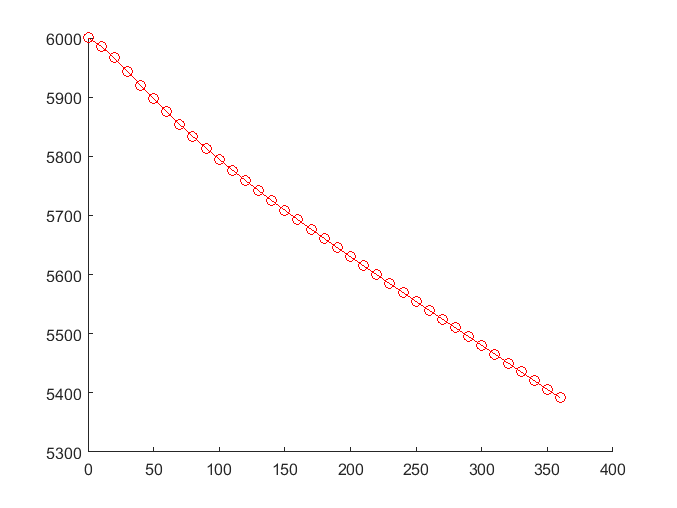

Error using plot
Vectors must be the same length.

    for j=1:(info.Time/d{i})+1
        test2(j)=test(cordinates(2), cordinates(1), cordinates(3),j);
    end
    plot(0:d{i}:info.Time,test2,char(linespec(i)),'DisplayName',name);
    clear('test','test2')
end
legend
ylabel('Pressure (psi)');
xlabel('Time (Day)');
t = annotation('textbox');
t.FontSize = 9;

t.String = ["Process Time",string(sum(tend)),"min"];
t.Position=[0.71 0.6 0.18 0.15];
clc